clear all
%syms s R1 R2 Cd Ci
syms s
R1=10

R1 = 10

R2=100

R2 = 100

Cd=0.1

Cd = 0.1000

Ci=0.001

Ci = 1.0000e-03


Z1 = R1/(R1*Cd*s + 1)

$$Z1 = \frac{10}{s+1}$$

Z2 = R2 + (1/(s*Ci))

$$Z2 = \frac{1000}{s}+100$$

Kp=-(Cd/Ci+R2/R1)

Kp = -110

Ki=-1/(Ci*R1)

Ki = -100

Kd=-Cd*R2

Kd = -10


T=Kp+Kd*s+Ki/s

$$T = -10\,s-\frac{100}{s}-110$$


[n,d]=numden(T)

$$n = -10\,s^{2}-110\,s-100$$

$$d = s$$

num=double(coeffs(n,'All'))

num =    -10  -110  -100


den=double(coeffs(d,'All'))

den =      1     0


H=tf(num,den)

H =
 
  -10 s^2 - 110 s - 100
  ---------------------
            s
 
Continuous-time transfer function.



U=tf([1],[0.0000000000001 1])

U =
 
       1
  -----------
  1e-13 s + 1
 
Continuous-time transfer function.



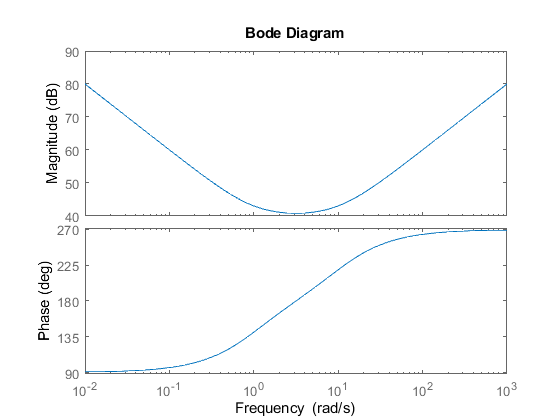

bode(H)

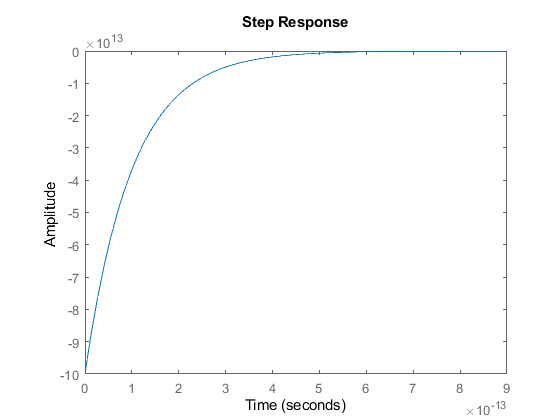

step(H*U)